clc;
clear all;
close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
k=9;%cambia esto
A = imread(string(fullfile(img_path, T{k,1})));%Voy a buscar el OD de esta imagen


%directory_img = ('D:\MAIA_sem01\image processing\project\test\test\newdata_image');
%directory_gt = ('D:\MAIA_sem01\image processing\project\test\test\newdata_image');

%listing_img = dir(fullfile(directory_img,'*.jpg'));
%listing_gt = dir(fullfile(directory_gt,'*.bmp'));

%im = struct2cell(listing_img);
%gtm = struct2cell(listing_gt);

%DC_disk_all=[];
%DC_cup_all=[];

 %for i = 1:size(im,2)

   %  name_img = im{1,i};
   %  name_gtm = gtm{1,i};

%R = imresize(img, 0.25);


% imbmp=imread(name_gtm);

% subplot(3,4,1);
% imshow(imbmp);
% title('Fundus Images');


img=imread(string(fullfile(img_path, T{k,1})));%Voy a buscar el OD de esta imagen


img = 768×576×3 uint8 array
img(:,:,1) =

     1     1     0     0     0     2     1     0     0     2     2     0     2     2     2     1     1     1     1     0     0     0     1     1     1     1     0     0     1     1     1     1     2     2     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     2     2     0     0     1     1     1     1     0     0     1     0     0     0     0     2     1     2     2     1     1     1     1     1     1     1     0     0     1     1     1     0     0     0     1     1     0     1     2     1     1     1     1     0     0     0     0     1     1     0     0     0     0     1     1     1     1     1     1     1     2     0     0     2     2     1     1     3     3     4     4     3     3     2     3     0     0     1     6    13    15    23    36    49    58    64    67    65    64    63    62    63    64    62    58    54    53    56    59    56    57    59    56    56    54    53    54    

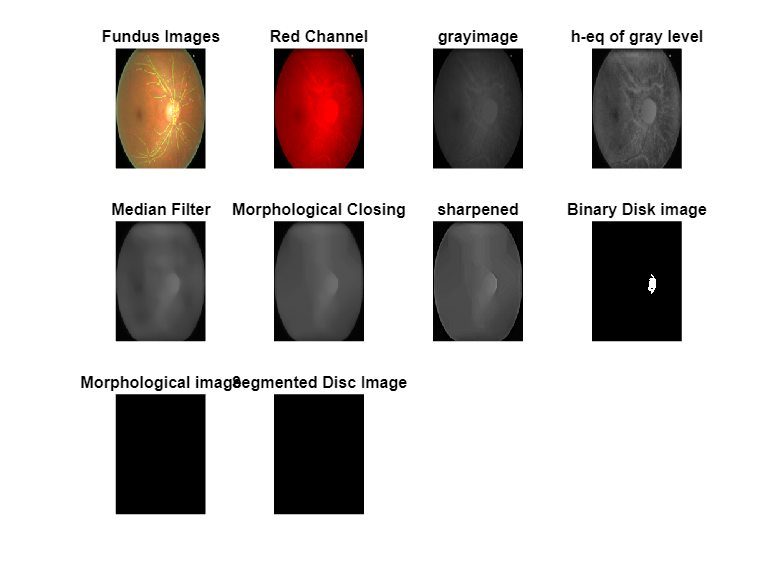

R = imresize(img, 0.25);
 figure(1)
subplot(3,4,1);
imshow(R);
title('Fundus Images');

 %% Separating channels
imR = R;
imR(:,:,2:3)=0;
subplot(3,4,2);
imshow(imR);
title('Red Channel');
%% RGB to GRAy
imL = rgb2gray(imR);
subplot(3,4,3);
imshow(imL);
title ('grayimage');
%% histogram of the gray image
% subplot(4,4,4); 
% imhist(imL);title('histogram');

%% equlization
%imh=imadjust(imL,stretchlim(imL), []);
imh= adapthisteq(imL);
subplot(3,4,4); 
imshow(imh);
title('h-eq of gray level');
% WE HAVE TO DO THE filtering here
%also the adaptive thrsholding 


%% median filter
J = medfilt2(imh,[19 19]);
subplot(3,4,5); 
imshow(J);
title('Median Filter');

% %% stretching again
% imh=imadjust(imC,[0.1,0.25], [0.0,1.0]);
% subplot(4,3,8);
% imshow(imh);
% title('After h-s of gray level');

%% morphological operation only closing
SE=strel('disk',40);
subplot(3,4,6); 
imC=imclose(J,SE);
imshow(imC);
title('Morphological Closing');


%% sharpening 
b = imsharpen(imC,'Radius',2,'Amount',2);
subplot(3,4,7);
imshow(b);
title('sharpened');

% %% stretching again equalization
% imEQ=imadjust(b,stretchlim(b), []);
%%
% imEQ= adapthisteq(b);
% %figure
% figure(1)
% subplot(4,4,8);
% imshow(imEQ);
% title('h-eq of sharpned image');

%% THRESHOLDING

subplot(3,4,8); 
imD = b>(max(stretchlim(b)*255));
imshow(imD);
title('Binary Disk image');


%% morphological operation erosion and dilation(to get better results)
imM=imerode(imD,strel('disk',11));
imN=imdilate(imM,strel('disk',21));
subplot(3,4,9); 
imshow(imN);
title('Morphological image');

%% segmentation
im1=double(R);
im2=double(imN);
for(i=1:3)
    im3(:,:,i)=im2.*im1(:,:,i);
end
imDisk=uint8(im3);
figure(1)
subplot(3,4,10);
imshow(imDisk),title('Segmented Disc Image');


%% elipse fitting
Igray = rgb2gray(imDisk);
BW = imbinarize(Igray);
% Extract the maximum area
BW = imclearborder(BW);
BW = bwareafilt(BW,1);
% Calculate centroid, orientation and major/minor axis length of the ellipse
s = regionprops(BW,{'Centroid','Orientation','MajorAxisLength','MinorAxisLength'});
% Calculate the ellipse line
theta = linspace(0,2*pi);
col = (s.MajorAxisLength/2)*cos(theta);

Error using  / 
Not enough input arguments.

row = (s.MinorAxisLength/2)*sin(theta);
M = makehgtform('translate',[s.Centroid, 0],'zrotate',deg2rad(-1*s.Orientation));
D = M*[col;row;zeros(1,numel(row));ones(1,numel(row))];
% Visualize the result

figure(1)
subplot(3,4,11);
imshow(Igray)
title('Labeling of Disc Image');
hold on
plot(D(1,:),D(2,:),'g','LineWidth',1)
%F=[D(1,:),D(2,:)];

subplot(3,4,12);
imshow(R);
title('Labeling on fundus image');
hold on
plot(D(1,:),D(2,:),'g','LineWidth',1)
% 
%% cup segmentation 
figure(2)
subplot(3,4,1);
imshow(imDisk);
title('Disc image');
%green chanel
T=imDisk;
%G=T(:,:,2);
T(:,:,1:2:3)=0;
subplot(3,4,2);  
imshow(T);
title('green chanel');

GC=rgb2gray(T);
subplot(3,4,3);
imshow(GC);
title('Gray image');

%% inverse 
J3=255-GC;
subplot(3,4,4);
imshow(J3);
title('inversed image');




%% opening
CEO1=strel('disk',40);
subplot(3,4,5);
imOP=imopen(J3,CEO1);
imshow(imOP);
title('Morphological opening');

%% histogram equalization 

subplot(3,4,6);
%imhso=imadjust(imOP,stretchlim(imOP),[]);
imhso= adapthisteq(imOP);
imshow(imhso);
title('Histogram equalization on M-O');




%% centroid

[m n]=size(imN);
rowt=0;colt=0;
for p=1:m
    for q=1:n
        if (imN(p,q)>0)
            rowt=[rowt p];
            colt=[colt q];
        end
    end
end
rowm=round(mean(rowt));
colm=round(mean(colt));

%% k means

imCK1=imsegkmeans(imhso,3);

% figure(8)
% subplot(121)
% imshow(imOP)
subplot(3,4,7);
imshow(imCK1,[]);
title('Clustered image');

imCK2=imCK1;

for p=1:m
    for q=1:n
        if (imCK1(p,q)~=imCK1(rowm,colm))
            imCK2(p,q)=mode(imCK1(rowm,:));
        end
    end
end

imCK3=imCK2;
if (mode(imCK2(rowm,:))~=min(imCK2(rowm,:)))
    imCK3=max(imCK2(rowm,:))-imCK2;
end

%% segmentation of the cup 

for p=1:m
    for q=1:n
        if (imCK3(p,q)==mode(imCK2(rowm,:)))
            imCK3(p,q)=0;
        else
            imCK3(p,q)=1;
        end
    end
end

im11=double(imDisk);
im22=double(imCK3);

for(i=1:3)
    im31(:,:,i)=im22.*im11(:,:,i);
end
imcup=uint8(im31);

subplot(3,4,8);
imshow(imcup);
title('Segmented cup Image');



%% ellipse fitting

Igray2 = imCK3;
BW2 = imbinarize(Igray2);
% Extract the maximum area
BW21 = imclearborder(BW2);
BW22 = bwareafilt(BW21,1);
% Calculate centroid, orientation and major/minor axis length of the ellipse
s2 = regionprops(BW22,{'Centroid','Orientation','MajorAxisLength','MinorAxisLength'});
% Calculate the ellipse line
theta = linspace(0,2*pi);

if isempty(s2)==1
    %continue
elseif isempty(s2)==1
   % continue
end

col = (s2.MajorAxisLength/2)*cos(theta);
row = (s2.MinorAxisLength/2)*sin(theta);
M2 = makehgtform('translate',[s2.Centroid, 0],'zrotate',deg2rad(-1*s2.Orientation));
D2 = M2*[col;row;zeros(1,numel(row));ones(1,numel(row))];
% Visualize the result

subplot(3,4,9);
imshow(imcup),
title('labeled cup');
hold on
plot(D2(1,:),D2(2,:),'g','LineWidth',2)% cup label
%F=[D(1,:),D(2,:)];

subplot(3,4,10);
imshow(R)
title('Labeled Cup and Disc');
hold on
plot(D(1,:),D(2,:),'g','LineWidth',1)
hold on
plot(D2(1,:),D2(2,:),'g','LineWidth',1)
% results
%disk
figure
subplot(1,2,1);
imshow(R);
title('Fundus Image');
subplot(1,2,2);
imshow(R);
title('Labeling on fundus image');
hold on
plot(D(1,:),D(2,:),'g','LineWidth',1);

% cup
figure

subplot(1,3,1);
imshow(R);
title('Fundus Image');
subplot(1,3,2);
imshow(imcup);
title('labeled cup');
hold on
plot(D2(1,:),D2(2,:),'g','LineWidth',2)% cup label
%F=[D(1,:),D(2,:)];

subplot(1,3,3);
imshow(R);
title('Labeled Cup and Disc');
hold on
plot(D(1,:),D(2,:),'g','LineWidth',1);
hold on
plot(D2(1,:),D2(2,:),'g','LineWidth',1);

%%
figure;
b_cup = imCK3*255;
imshow(b_cup);
title('Segmented cup Image');
figure;
b_disk = rgb2gray(imDisk);

%% load ground truth

gt_total=imresize(imbmp, 0.25);
gt_od = ~(gt_total>(200));
figure
imshow(gt_od);
gt_cup = gt_total<(100);
figure
imshow(gt_cup)

%% dice score

DC_disk=dice(logical(gt_od),logical(b_disk))
DC_cup=dice(logical(gt_cup),logical(b_cup))

DC_disk_all=[DC_disk_all DC_disk];
DC_cup_all=[DC_cup_all DC_cup];

%end

DC_disk_avg=mean(DC_disk_all,'all')
DC_cup_avg=mean(DC_cup_all,'all')